Question 1 Convergence Region

a) Using the function f(x,y) = -cos(x)cos(y/5)

the hessian matrix is equal to 

[cos(x)*cos(y/5)  -1/5*sin(x)*sin(y/5);

-1/5*sin(x)*sin(y/5) 1/25*cos(x)*cos(y/5)]

For this hessian matrix to be positive definite its leading submatrix must be positive and determinant should be positive. Therefore cos(x)*cos(y/5) > 0 and det = 1/25[cos^2(x)*cos^2(y/5)-sin^2(x)*sin^2(y/5)]>0

b) steepestdescent.m

c) newton2.m 

d)

clf
x = linspace(-pi/2, 1/2*pi, 15);
y = linspace(-5*pi/2, 5/2*pi, 15);
hold on;
for i=1:15
    for j=1:15
        if steepestdescent(x(i),y(j)) 
            scatter(x(i),y(j),[],'b');
        else
            scatter(x(i),y(j),[],'r');
        end
    end
end
hold off;

clf
x = linspace(-pi/2, 1/2*pi, 15);
y = linspace(-5*pi/2, 5/2*pi, 15);
hold on;
for i=1:15
    for j=1:15
        if newton2(x(i),y(j)) 
            scatter(x(i),y(j),[],'b');
        else
            scatter(x(i),y(j),[],'r');
        end
    end
end
hold off;

the script will take very long time to run(approx 5 min) and it will result graph like this 

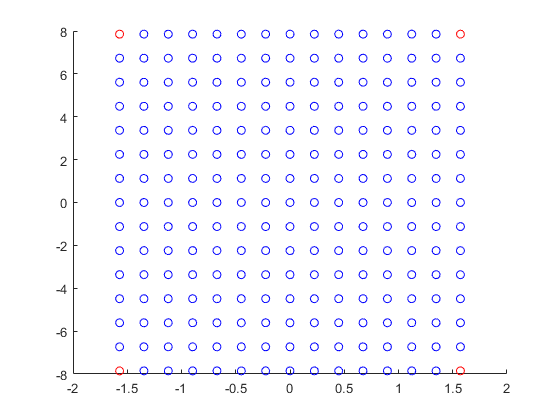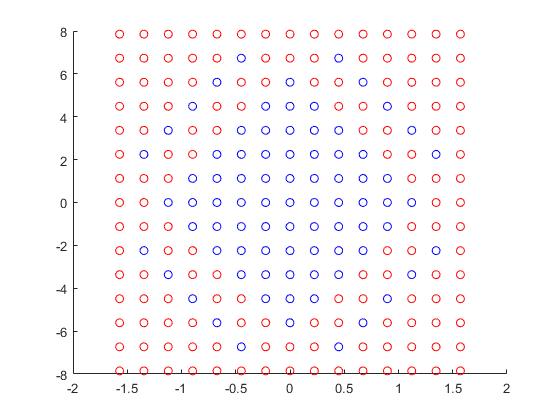

left is the steepest method and right is netwon method. Blue shows convergences while red shows non-convergence. It seems steepest descent have wider convergence region.